# Modelo *E.coli*

**Autor:** H. Scott Hinton, Utah State University

**Editado y traducido:** German Preciat, Universidad de Guadalajara

## INTRODUCCIÓN

El propósito de este tutorial es mostrarle a un principiante cómo se puede usar COBRA Toolbox para explorar la fisiología de una célula. Para ilustrar las capacidades de COBRA Toolbox [1, 2], este tutorial se centrará en explorar los atributos del modelo central de *E.coli* que fue desarrollado por Orth, Fleming y Palsson [3] y está incluido en la instalación estándar de COBRA Toolbox. Este tutorial no se centrará en la fisiología detallada representada por el modelo central, ya que se ha publicado en detalle en otro lugar [3], sino que se centrará en cómo utilizar COBRA Toolbox para explorar el núcleo de E.coli o cualquier otro modelo basado en COBRA. .

Este tutorial incluirá discusiones pragmáticas de los siguientes temas:

- Las limitaciones del modelado basado en restricciones.

- Componentes básicos de un modelo COBRA que incluyen: A) genes, B) reacciones, C) metabolitos, D) asociaciones gen-proteína-reacción, E) restricciones y F) funciones objetivas.

- Una descripción general del análisis de balance de flujo (FBA).

- Los subsistemas del modelo central de* E.coli* que incluyen secciones sobre A) gestión de la energía de la célula, B) vía de la glucólisis, C) vía de las pentosas fosfato, D) ciclo del ácido tricarbonoxilico, E) ciclo del glucoxilato, gluconeogénesis y reacciones anapleuróticas, F) fermentación, y G) el metabolismo del nitrógeno.

## MATERIALES

Este tutorial se basa en la caja de herramientas de análisis y reconstrucción basada en restricciones (COBRA Toolbox) [2,3] que se encuentra en constante en desarrollo. Para usar este tutorial, necesitará la versión 2018b o más reciente de Matlab ([https://www.mathworks.com/](https://www.mathworks.com/)) y el software de COBRA Toolbox se puede descargar desde [https://github.com/opencobra/cobratoolbox](https://github.com/opencobra/cobratoolbox). Las instrucciones de instalación y los consejos para la solución de problemas también están disponibles en este sitio web.

## **CONFIGURACIÓN DEL EQUIPO**

Para utilizar COBRA Toolbox, primero debe inicializar el entorno de Matlab para incluir todas las funciones de COBRA Toolbox. Antes de inicializar COBRA Toolbox, inicie Matlab y muévase al directorio de Matlab que desea que sea su directorio de trabajo. La inicialización de COBRA Toolbox se logra con la función "`initCobraToolbox`" como se muestra a continuación. *[Tiempo: < Minuto]*

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.39.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)...
***Local changes to submodules have been stashed. See https://git-scm.com/docs/git-stash.
Entering 'binary'
No local changes to save
Entering 'external/analysis/Cn

 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] GUROBI_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] MOSEK_PATH: /Applications/Mosek/10.2/
   Done.
 > Checking available solvers and solver interfaces ...Gurobi installed at this location? 
Licence file current? 


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
ϰ
License cannot be located. The default search path is ':/Users/eduardoruiz/mosek/mosek.lic:'.

MSK_RES_ERR_MISSING_LICENSE_FILE

 > [matlab] Primal optimality condition in solveCobraLP satisfied.
   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   -------

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    1 	    - 	    1 	    - 	    - 	    1
	matlab       	active        	    1 	    - 	    - 	    - 	    1 	    -

% change to the directory of the tutorial
cd(fileparts(which('tutorial_ecoliCoreModel_part1.mlx')));

**SOLUCIÓN DE PROBLEMAS**

Uno de los mayores problemas que enfrentan los usuarios de este tutorial es que no han configurado correctamente el "solver" antes de comenzar el tutorial. Esto es necesario para las optimizaciones de red requeridas por este tutorial. Esto se puede hacer seleccionando el solucionador apropiado para la máquina que está utilizando eliminando el signo "%" (comentario) solo para el solucionador deseado. *[Tiempo: segundos]*

% changeCobraSolver('glpk', 'all');

## PROCEDIMIENTO

## 1. Modelado basado en restricciones

Tanto las reconstrucciones de redes metabólicas a escala del genoma [4] como el modelado basado en restricciones [5,6,7] se pueden usar para modelar fenotipos de estado estacionario durante la fase de crecimiento exponencial. Esto puede ser útil para explorar y comprender las capacidades de cada fenotipo. También se puede utilizar para identificar y modificar vías celulares para favorecer fenotipos productores de bioproductos específicos. Es importante entender que la mayoría de los modelos basados en restricciones no pueden

- Modelar transiciones entre fenotipos,

- Incluir los genes necesarios para la fase estacionaria (proteasas, etc.),

- Incluyen las rutas completas de transcripción y traducción.

Estos modelos basados en restricciones se basan en una función de biomasa que representa la carga metabólica promedio requerida durante el crecimiento celular exponencial. Representa los porcentajes medios de las partes componentes (aminoácidos, nucleótidos, energía, etc.) que se incluyen en 1 g de peso seco por hora de biomasa celular.

Mediante el uso de reconstrucciones de redes metabólicas a escala genómica, el análisis de equilibrio de flujo (FBA) [8] se puede utilizar para calcular el flujo de metabolitos a través de una red metabólica (unidad de flujo = $\textrm{mol}/\textrm{gDW}/\textrm{hr}$). Esta capacidad hace posible predecir la tasa de crecimiento de un organismo y/o la tasa de producción de un metabolito dado. ¡Es importante que se entienda que FBA tiene limitaciones! No utiliza parámetros cinéticos, por lo que no puede predecir las concentraciones de metabolitos. Además, solo es capaz de determinar flujos en estado estacionario. Finalmente, la FBA tradicional no tiene en cuenta los efectos reguladores, como la activación de enzimas por las proteínas quinasas o la regulación de la expresión génica. Por lo tanto, sus predicciones pueden no ser siempre precisas.

En este tutorial, mostraremos algunos ejemplos sencillos utilizando la toolbox de Matlab COnstraint-Based Reconstruction and Analysis (COBRA Toolbox) [4,5], un paquete de software que funciona en el entorno de programación Matlab ([https://www.mathworks.com/](https://www.mathworks.com/)). . Como verá, COBRA Toolbox permite a los usuarios explorar el funcionamiento de un modelo de celda con solo unas pocas líneas de código. Estos resultados se pueden usar para predecir el comportamiento celular que, en algunos casos, se ha verificado experimentalmente.

## **2. Componentes básicos de un modelo COBRA**

COBRA Toolbox se basa en reconstrucciones de redes metabólicas que son bases de datos estructuradas bioquímica, genética y genómicamente (BiGG) compuestas de reacciones bioquímicas y metabolitos [9,10]. Almacenan información metabólica del organismo celular, como la estequiometría de la reacción, la reversibilidad de la reacción y las relaciones entre genes, reacciones y proteínas (enzimas). Aunque muchos organismos tienen redes metabólicas centrales similares, puede haber diferencias significativas incluso entre dos organismos estrechamente relacionados, por lo tanto, las reconstrucciones de redes metabólicas son específicas del organismo [4]. Un modelo simplificado de *E.coli*, denominado modelo central de *E.coli*, es un gran modelo para explorar las herramientas de análisis y exploración disponibles a través de la COBRA Toolbox, que es el objetivo de este tutorial. El mapa metabólico del modelo central de *E.coli* se muestra a continuación en la Figura 1. En esta figura, las letras más grandes en este mapa (Glyc, PPP, etc.) se refieren a los principales subsistemas incluidos en este modelo simple que incluye; (OxP) fosforilación oxidativa o gestión de la energía de la célula, vía de la glucólisis (Glyc), vía de la pentosa fosfato (PPP), ciclo del ácido tricarboxílico (TCA), ciclo del glucoxilato (Ana), gluconeogénesis y reacciones anapleuróticas, fermentación (Ferm) y (N) metabolismo del nitrógeno. Todos estos subsistemas se analizarán con más detalle más adelante en este tutorial.

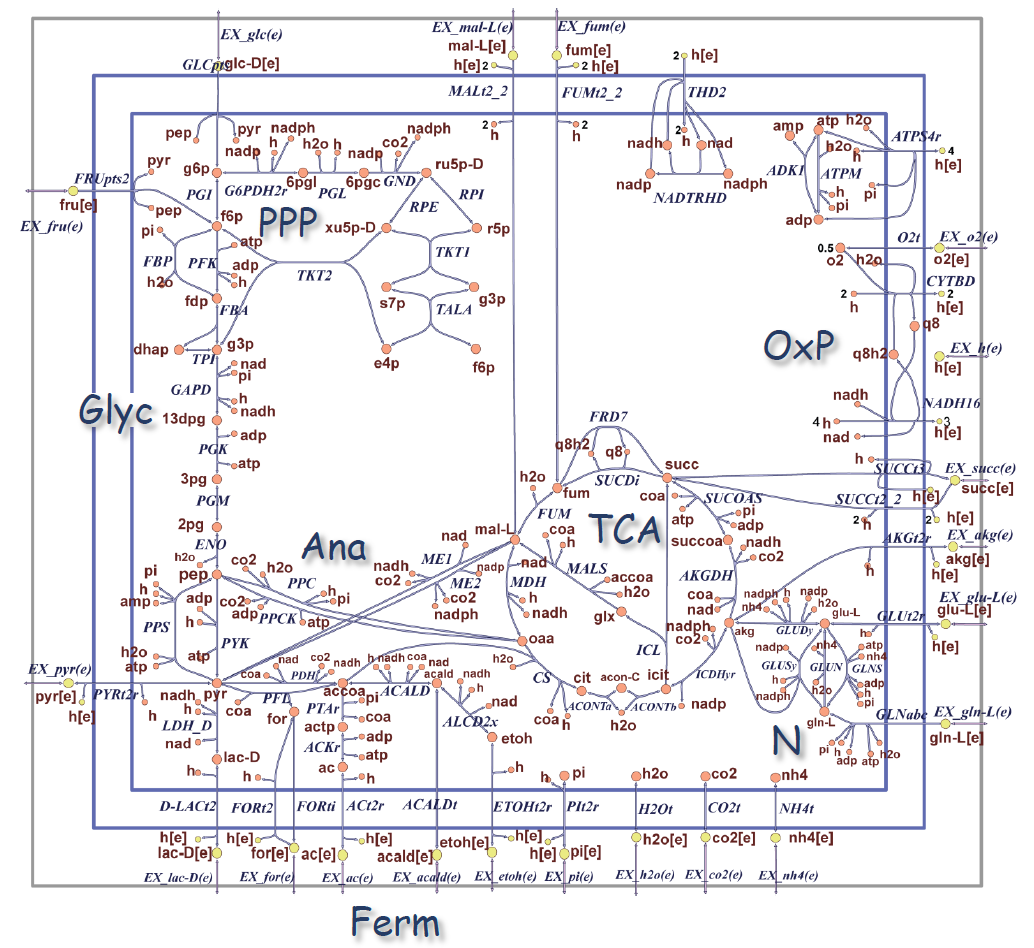

**Figura 1**. Mapa metabólico del modelo central de *E.coli* [3].

Una reconstrucción metabólica consta de una colección de genes, reacciones que representan proteínas (enzimas), metabolitos, una matriz estequiométrica que define la relación entre las reacciones y los metabolitos, restricciones de reacción y una función de biomasa. Los genes en el modelo están representados por el nombre del gen y el locus genómico. Los metabolitos se representan con caracteres en minúsculas y, por lo general, tienen un sufijo que representa el compartimento en el que operan. Para el modelo central simplificado de *E.coli*, solo se representan dos compartimentos; metabolitos citosólicos con el sufijo "`[c]`" y metabolitos extracelulares con el sufijo "`[e]`". Para simplificar este modelo, el modelo central de *E.coli* no distingue entre el espacio periplásmico y el medio extracelular. La representación de metabolitos del modelo COBRA incluye una abreviatura, el nombre oficial, la fórmula química y la carga del metabolito.

Las reacciones en los modelos COBRA corresponden a las enzimas en una celda y se representan mediante abreviaturas en mayúsculas, un nombre oficial y una fórmula estequiométrica. Los sufijos utilizados en las abreviaturas de reacción incluyen; '`i`' (irreversible), '`r`' (reversible), '`abc`' (transportador de cassette de enlace ATP) y '`t`' (transporte). La mayoría de las reacciones utilizadas en el modelo llevan el nombre de las enzimas que las catalizan. Como ejemplo, `ENO` representa la enzima "enolasa" e incluye la fórmula "`2pg[c] <=> h2o[c] + pep[c]`". Un tipo especial de reacción que se encuentra en los modelos COBRA son las reacciones de intercambio que tienen la forma de "`EX_xxx(e)`" y se utilizan para secretar/captar metabolitos hacia/desde el espacio extracelular. Como ejemplo, la reacción de intercambio de glucosa es "`EX_glc(e)`".

Los modelos COBRA también incluyen reglas booleanas para cada reacción que describen la relación gen-reacción. Por ejemplo, 'gen1 y gen2' indican que los dos productos génicos son parte de una enzima, mientras que 'gen1 o gen2' indican que los dos productos génicos son isoenzimas que catalizan la misma reacción. Las asociaciones gen-proteína-reacción (GPRA) para en la Figura 2 se muestran algunas reacciones. Cada GPRA se compone de un locus de gen, un péptido traducido (ARNm) y proteínas funcionales que trabajan juntas para hacer una sola reacción (enzima). En la parte superior de cada GPRA se destaca una parte del contexto genómico. Los genes en esta figura están designados por su nombre de locus y representados por cuadros de color azul claro. Los péptidos traducidos están representados por recuadros morados, las proteínas funcionales están representadas por óvalos rojos, mientras que las reacciones están etiquetadas con recuadros azul oscuro. Como se puede ver en la figura, las isoenzimas incluyen dos proteínas diferentes que están conectadas a la misma reacción. Para el caso de proteínas con múltiples subunidades peptídicas, los péptidos están conectados con un signo '&' sobre la proteína. Para complejos de muchas proteínas funcionales, las proteínas también están conectadas con un signo '`&`' encima de la reacción. Ciertos genes que son responsables de la creación de una reacción dada, como pykF y pykA, pueden ser codificados por genes en operones que están muy separados en el genoma. En esta figura, los operones están representados por rectángulos sombreados alrededor de uno o más genes. Los genes están representados por rectángulos con un lado apuntado para indicar la dirección de la hebra sentido. Otros operones pueden contener múltiples genes que codifican subunidades de proteínas en proteínas más grandes. Como ejemplo, el mismo operón sdhCDAB-sucABCD que codifica las proteínas SUCDi también codifica dos proteínas del complejo enzimático 2-oxoglutarato deshidrogenasa, AKGDH.

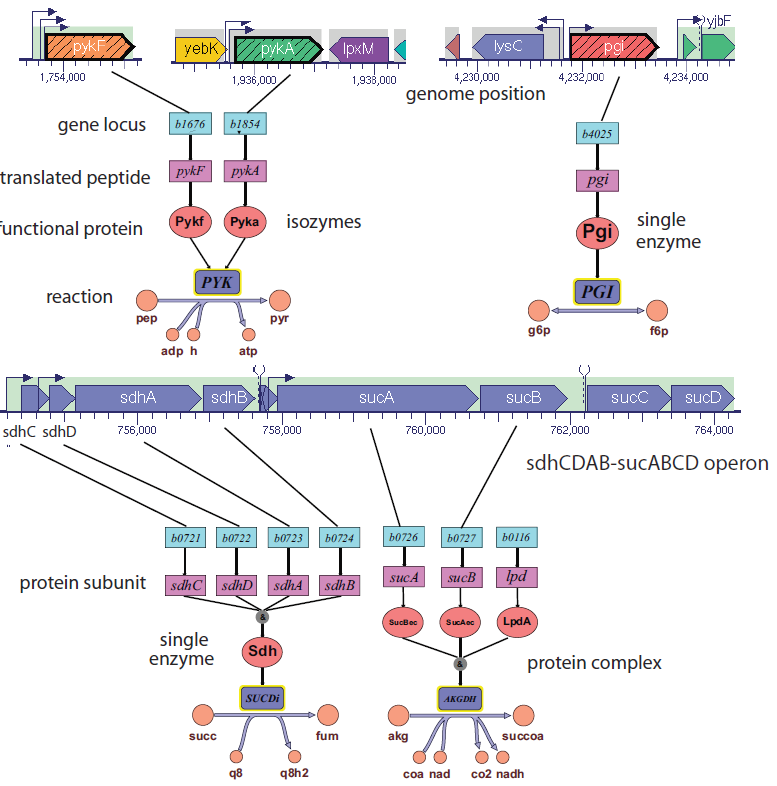

**Figura 2.** Ejemplos de asociaciones gen-proteína-reacción del modelo central de *E.coli* [3].

Ahora comencemos a usar COBRA Toolbox para comenzar a explorar el modelo central de *E.coli*. Lo primero que hay que hacer es cargar el modelo en el entorno de trabajo de Matlab. Esto se puede lograr cargando la versión de Matlab del modelo (.mat) en Matlab. Este modelo está disponible en el software de COBRA Toolbox descargado. *[Tiempo: segundos]*

global CBTDIR
model = readCbModel([CBTDIR filesep 'test' filesep 'models' filesep 'mat' filesep 'ecoli_core_model.mat']);

Each model.subSystems{x} is a character array, and this format is retained.


e_coli_core = model; % Guardar el modelo original para su uso posterior

Después de cargar el modelo central de *E.coli* en Matlab, debería poder mirar el lugar de trabajo de MATLAB y ver que el modelo está cargado como se muestra en la Figura 3.

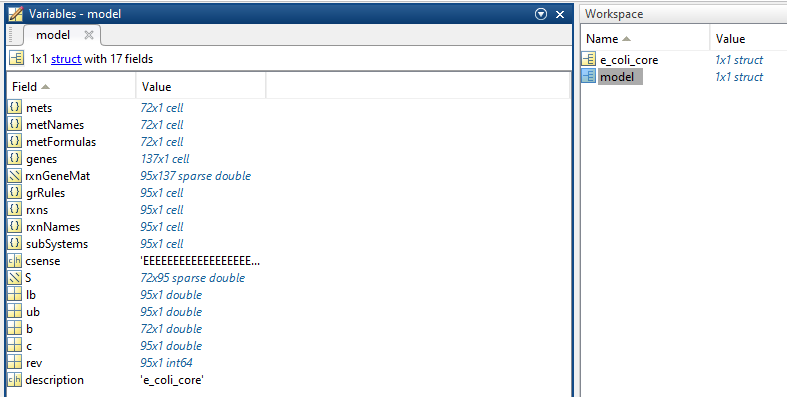

**Figura 3.** Espacio de trabajo de Matlab después de cargar el modelo central de *E.coli* en Matlab.

Quizás la forma más fácil de acceder a toda la información del modelo COBRA es imprimir una hoja de cálculo que contenga toda la información almacenada en el modelo. Esto se puede lograr usando la función "`writeCbModel`". *[Tiempo: segundos]*

outmodel = writeCbModel(model)

outmodel = struct with fields:
              S: [72×95 double]
           mets: {72×1 cell}
              b: [72×1 double]
         csense: [72×1 char]
           rxns: {95×1 cell}
             lb: [95×1 double]
             ub: [95×1 double]
              c: [95×1 double]
      osenseStr: 'max'
          genes: {137×1 cell}
          rules: {95×1 cell}
    metFormulas: {72×1 cell}
       metNames: {72×1 cell}
        grRules: {95×1 cell}
     rxnGeneMat: [95×137 double]
       rxnNames: {95×1 cell}
     subSystems: {95×1 cell}
    description: 'ecoli_core_model.mat'
        modelID: 'model'


Esta función escribirá el modelo en una hoja de cálculo de Excel llamada "core_model.xls" y le permitirá explorar todos los detalles asociados con las reacciones y los metabolitos del modelo. Esto se ilustra en la Figura 4. También puede obtener información específica sobre genes, reacciones, metabolitos y GPRA utilizando las funciones de COBRA Toolbox. Esto se mostrará más adelante en este tutorial.

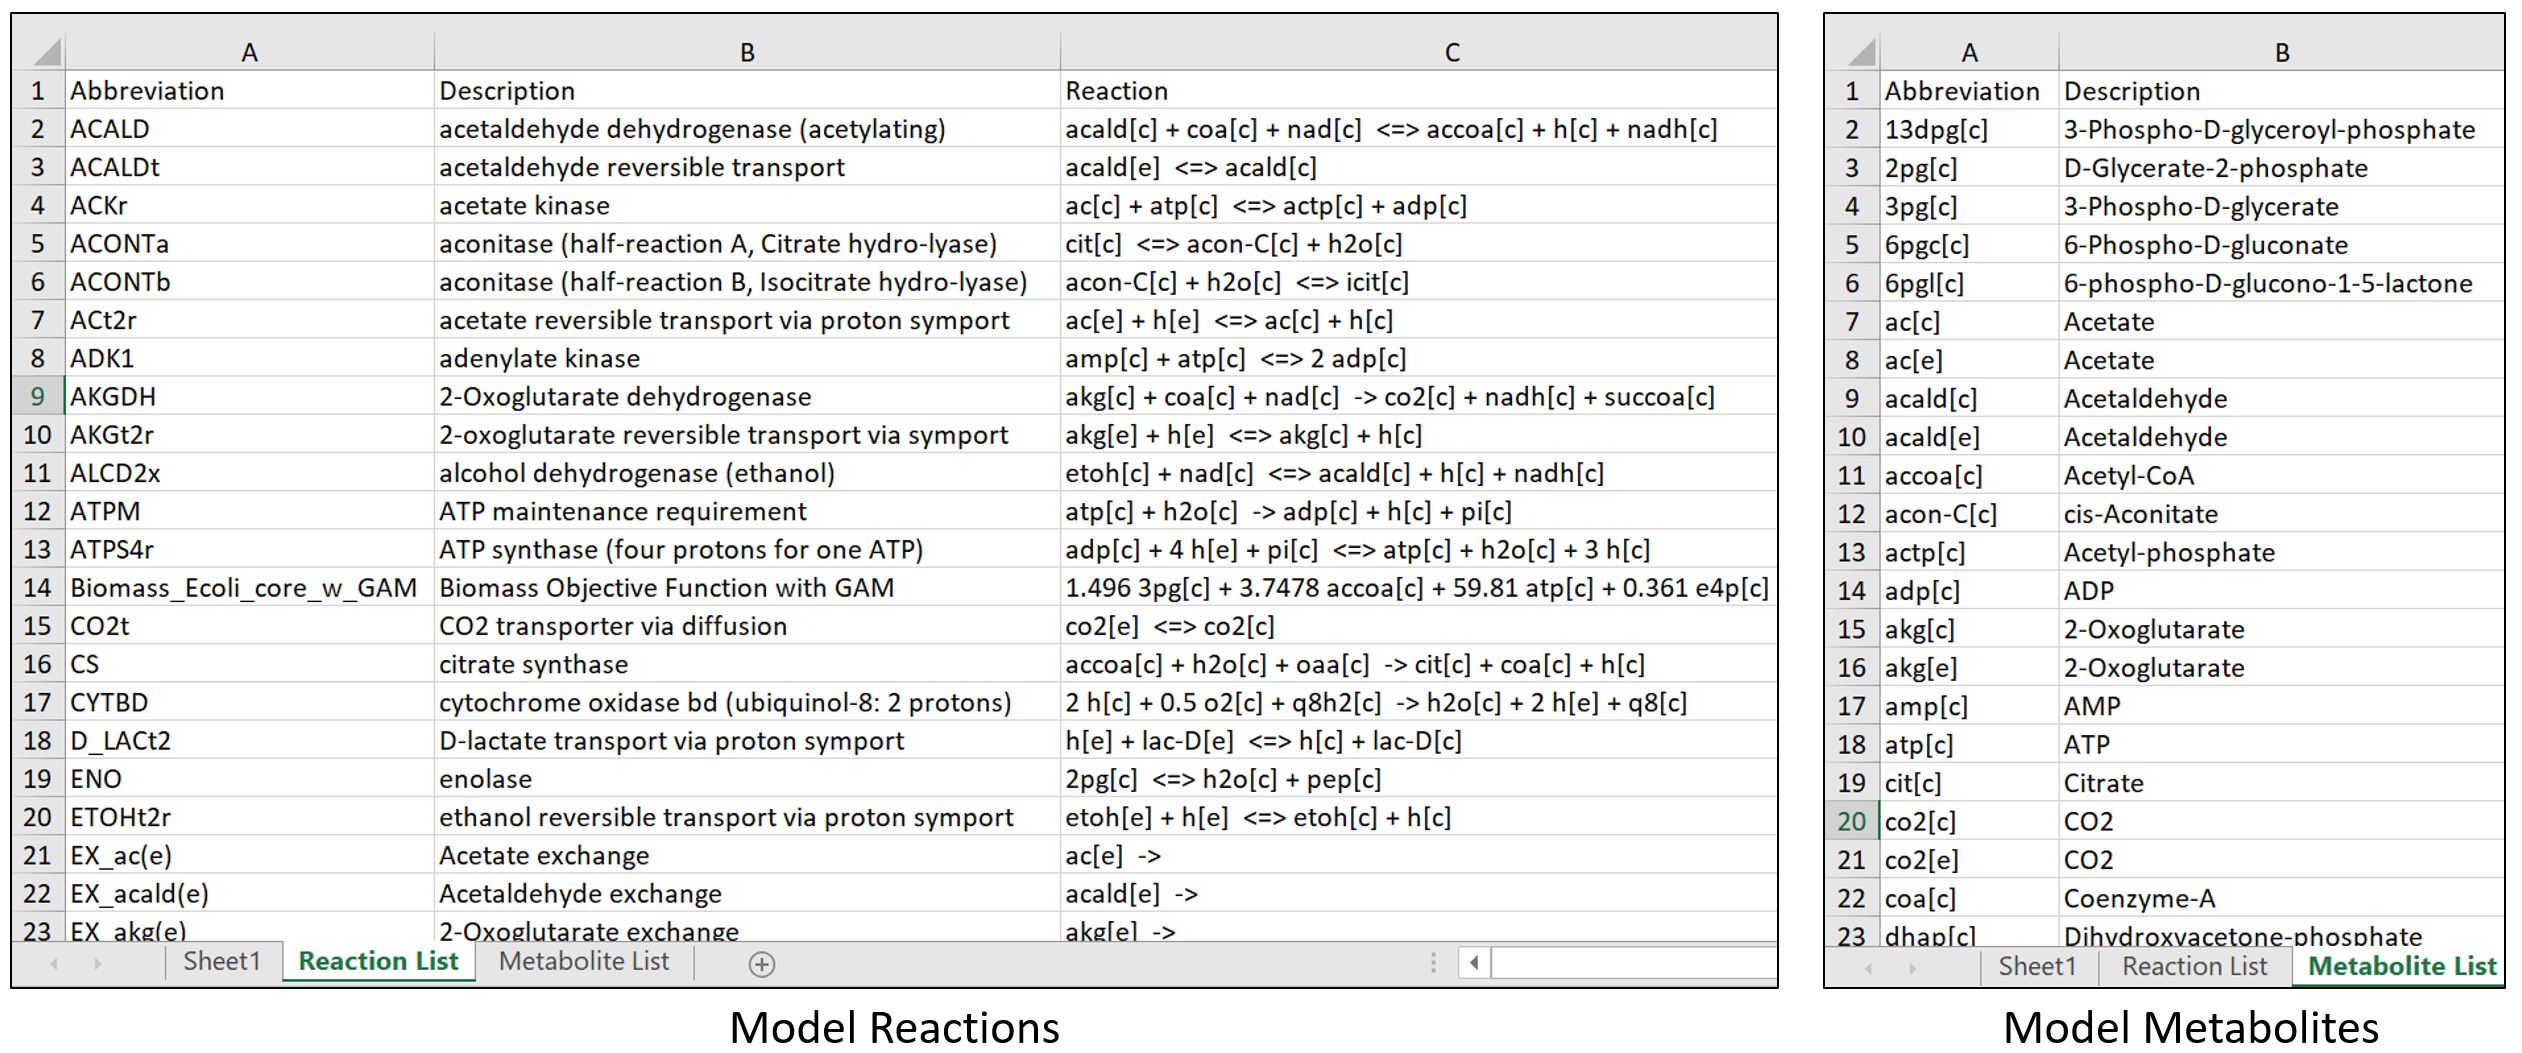

**Figura 4. **Captura de pantalla de "core_model.xls" que muestra una parte de la hoja de cálculo con reacciones y metabolitos del modelo.

Una forma de entender cómo funciona la célula es visualizar el funcionamiento de la célula a través de un mapa metabólico. Hay mapas disponibles en la instalación de la COBRA Toolbox para varios organismos diferentes que se pueden usar para visualizar los modelos y también superponer valores de flujo calculados en el mapa (discutiremos esto en la sección de análisis de balance de flujo). Para crear un mapa se requiere un archivo especial denominado "mapa de exportación". Para el caso del modelo central de *E.coli*, el mapa de exportación se denomina "ecoli_core_map.txt" y se incluye con la instalación predeterminada de la COBRA Toolbox. Los siguientes pasos se pueden usar para crear un mapa del núcleo de *E.coli* en un archivo "SVG" llamado "target.svg". Este archivo de mapa debe estar ubicado en su directorio de trabajo. *[Tiempo: segundos]*

map=readCbMap('ecoli_core_map.txt');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 100;
drawCbMap(map);

Document Written


La Figura 5 es una captura de pantalla del mapa central de* E.coli* producido por "drawflux".

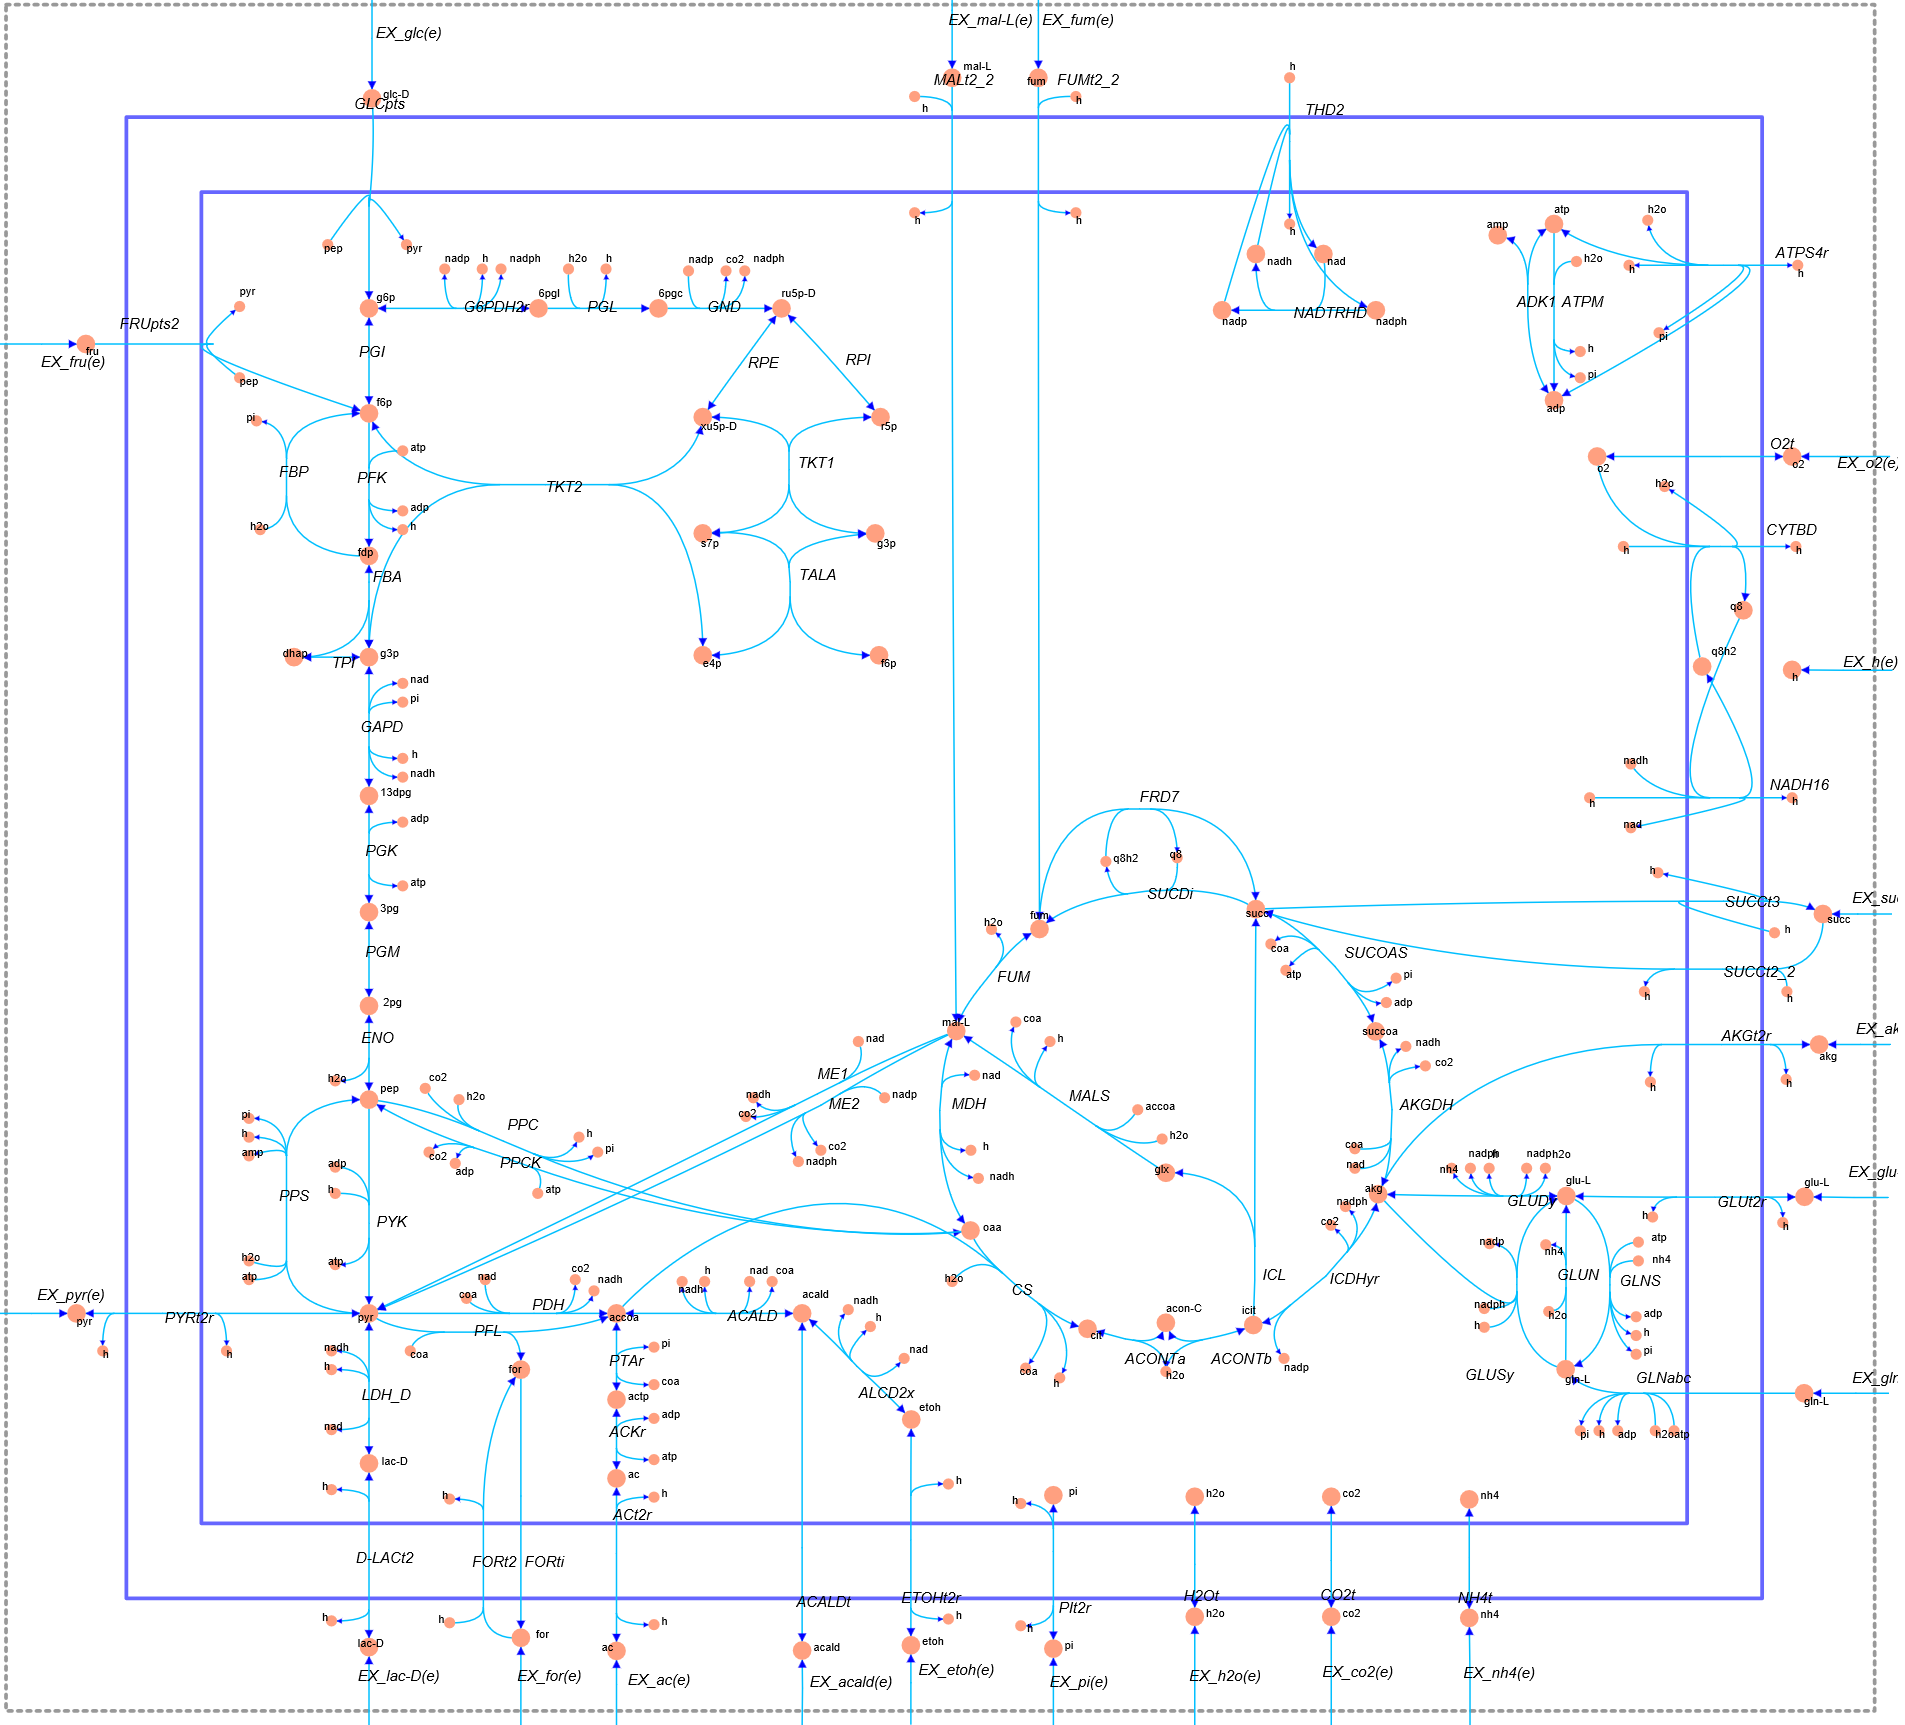

**Figure 5.** Captura de pantalla del mapa del modelo central de E.coli producido por "drawflux".

Este mapa SVG se puede leer con la mayoría de los navegadores y es muy fácil de usar para buscar y explorar la red *E.coli*.

### **2.A. Genes** 

Ahora, comencemos explorando algunas de las funciones del código Matlab y de la COBRA Toolbox que se pueden usar para extraer información sobre los genes del modelo. A continuación se muestra una colección de funciones de COBRA Toolbox que recuperan información clave de los genes en el modelo. Los genes solo están representados por su número de locus de gen (por ejemplo, b2097). El nombre del gen se puede obtener con una búsqueda rápida en el sitio web de EcoCyc ([https://www.ecocyc.org/](https://www.ecocyc.org/)). Para empezar, los genes incluidos en el modelo y sus geneID se almacenan en la estructura "model.genes". La función COBRA Toolbox "findGeneIDs" se puede utilizar para extraer el geneID de la estructura del modelo. Los primeros 10 genes del modelo y sus ID de genes se pueden imprimir de la siguiente manera. *[Tiempo: segundos]*

genes = cellstr(model.genes(1:10));
geneIDs = findGeneIDs(model, model.genes(1:10));
printLabeledData(model.genes(1:10),geneIDs)

b0008               	           1
b0114               	           2
b0115               	           3
b0116               	           4
b0118               	           5
b0351               	           6
b0356               	           7
b0451               	           8
b0474               	           9
b0485               	          10


Para el caso de encontrar un ID de gen único del modelo, el número de locus del gen debe incluirse entre comillas simples, como 'b_number'. *[Tiempo: segundos]*

findGeneIDs(model, 'b0116')

ans = 4

Ahora, para encontrar las reacciones asociadas con un gen dado, puede usar la función "`findRxnsFromGenes`" como se muestra a continuación. *[Tiempo: segundos]*

[results ListResults] = findRxnsFromGenes(model,'b0116', 0, 1)

results = struct with fields:
    gene_b0116: {2×5 cell}


ListResults = 2×6 cell array
    {'AKGDH'}    {'akg[c] + coa[c] + nad[c]  -> co2[c] + nadh[c] + succoa[c] '}    {'Citric Acid Cycle'         }    {'2-Oxoglutarate dehydrogenase'}    {'( b0116  and  b0726  and  b0727 )'}    {'gene_b0116'}
    {'PDH'  }    {'coa[c] + nad[c] + pyr[c]  -> accoa[c] + co2[c] + nadh[c] ' }    {'Glycolysis/Gluconeogenesis'}    {'pyruvate dehydrogenase'      }    {'( b0114  and  b0115  and  b0116 )'}    {'gene_b0116'}


Este resultado muestra que el gen "b0116" está asociado con las dos reacciones `AKGDH` y `PDH`.

### **2.B. Reacciones**

Las reacciones y sus rxnID se almacenan en la estructura "model.rxns" y los nombres de las reacciones se almacenan en "`model.rxnNames`". La función de COBRA Toolbox "`findRxnIDs`" se puede utilizar para extraer el rxnID de la estructura del modelo. Tenga en cuenta que la función de biomasa "`Biomass_Ecoli_core_w_GAM`" aparece como una de las reacciones. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, model.rxns(1:15));
printLabeledData(model.rxns(1:15),rxnIDs)

ACALD               	           1
ACALDt              	           2
ACKr                	           3
ACONTa              	           4
ACONTb              	           5
ACt2r               	           6
ADK1                	           7
AKGDH               	           8
AKGt2r              	           9
ALCD2x              	          10
ATPM                	          11
ATPS4r              	          12
Biomass_Ecoli_core_w_GAM	          13
CO2t                	          14
CS                  	          15


Para encontrar un solo rxnID del modelo, use "findRxnIDs" con la abreviatura de reacción deseada incluida entre comillas simples, p. '`ENO`'. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, 'ENO')

rxnIDs = 18

Encontrar el nombre de la reacción 'ENO' se puede recuperar usando la estructura "model.rxnNames" con la reacción deseada rxnID. *[Tiempo: segundos]*

model.rxnNames(rxnIDs)

ans = 1×1 cell array
    {'enolase'}


Para encontrar la fórmula de la reacción, use la función "`printRxnFormula`". *[Tiempo: segundos]*

printRxnFormula(model,'ENO');

ENO	2pg[c] 	<=>	h2o[c] + pep[c] 


Para encontrar los genes asociados con una reacción determinada, puede utilizar la función "`findGenesRxns`". *[Tiempo: segundos]*

[geneList]=findGenesFromRxns(model,'ENO');
geneList{1:1}

ans = 1×1 cell array
    {'b2779'}


Finalmente, hay momentos en los que es necesario encontrar todos los metabolitos "reactivos" que alimentan una reacción, así como todos los metabolitos "producto" que se producen en la reacción. Esto se puede lograr usando la función "`surfNet`" como se muestra a continuación (hay un tutorial COBRA sobre esto de Siu Hung Joshua Chan llamado "Browse Networks in the Matlab Command Window Using surfNet"). El resultado de esta función incluye una lista de los reactivos y productos basados en las fórmulas de reacción. Cabe señalar que en situaciones en las que una reacción se vuelve reversible, un metabolito que es un reactivo puede convertirse en un producto y un metabolito que es un producto puede convertirse en un reactivo. *[Tiempo: segundos]*

surfNet(model, 'GAPD')


Rxn #49  GAPD, Bd: -1000 / 1000, glyceraldehyde-3-phosphate dehydrogenase, grRules: b1779
g3p[c] + nad[c] + pi[c]   <=>   13dpg[c] + h[c] + nadh[c] 
  id   Met       Stoich     metNames, metFormulas
Reactant:
 #33     g3p[c]  -1         Glyceraldehyde-3-phosphate, C3H5O6P
 #50     nad[c]  -1         Nicotinamide-ad

En este caso, los metabolitos "reactivos" para la reacción GAPD son `g3p[c]`, `nad[c]` y `pi[c]` mientras que los metabolitos "producto" son `13dpg[c]`, `h[c]` y `nadh[c`] .

### **2.C. Metabolitos**

Los metabolitos incluidos en el modelo y sus ID de metabolitos (metID) se almacenan en la estructura "`model.mets`" y los nombres de los metabolitos se almacenan en `model.metNames`. La función de COBRA Toolbox "`findMetIDs`" se puede utilizar para extraer los metID de la estructura del modelo, como se muestra en el siguiente ejemplo. *[Tiempo: segundos]*

metIDs = findMetIDs(model, model.mets(1:15));
printLabeledData(model.mets(1:15),metIDs)

13dpg[c]            	           1
2pg[c]              	           2
3pg[c]              	           3
6pgc[c]             	           4
6pgl[c]             	           5
ac[c]               	           6
ac[e]               	           7
acald[c]            	           8
acald[e]            	           9
accoa[c]            	          10
acon-C[c]           	          11
actp[c]             	          12
adp[c]              	          13
akg[c]              	          14
akg[e]              	          15


Para encontrar un solo metID del modelo, use "`findMetIDs`" con la abreviatura del metabolito deseado incluida entre comillas simples, p. '`akg[c]`'. *[Tiempo: segundos]*

metIDs = findMetIDs(model, 'akg[c]')

metIDs = 14

Encontrar el nombre de la reacción '`akg[c]`' produce *[Tiempo: segundos]*

model.metNames(metIDs)

ans = 1×1 cell array
    {'2-Oxoglutarate'}


Para encontrar la fórmula química del metabolito, puede usar la estructura "`model.metFormulas`" con un metID. *[Tiempo: segundos]*

model.metFormulas(metIDs)

ans = 1×1 cell array
    {'C5H4O5'}


Finalmente, para encontrar reacciones que produzcan y consuman un metabolito deseado, puede volver a utilizar la función "`surfNet`". Esto incluye una lista de las reacciones de consumo y producción basadas en las fórmulas de reacción. En algunas situaciones, si una reacción es reversible, las reacciones de producción/consumo podrían intercambiarse. *[Tiempo: segundos]*

surfNet(model, 'atp[c]')


Met #17  atp[c], ATP, C10H12N5O13P3

Consuming reactions:
  #3  ACKr, Bd: -1000 / 1000, acetate kinase, grRules: (b3115 or b2296 or b1849)
ac[c] + atp[c]   <=>   actp[c] + adp[c] 
  #7  ADK1, Bd: -1000 / 1000, adenylate kinase, grRules: b0474
<a h

Como era de esperar, debería haber una gran cantidad de consumidores de `atp[c]` pero solo una pequeña cantidad de productores.

### **2.D. Gene-Protein-Reaction Associations**

Una asociación gen-proteína-reacción (GPRA) muestra la relación booleana entre los genes que se requieren para producir una reacción específica (consulte la Figura 2). La relación booleana entre los genes y una reacción dada se puede encontrar utilizando la estructura "`model.grRules`" del modelo. Esto se muestra a continuación. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, 'PYK');
model.grRules(rxnIDs)

ans = 1×1 cell array
    {'(b1854 or b1676)'}


Aquí hay un ejemplo de una relación gen-reacción más complicada. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model, 'ATPS4r');
model.grRules(rxnIDs)

ans = 1×1 cell array
    {'(((b3736 and b3737 and b3738) and (b3731 and b3732 and b3733 and b3734 and b3735)) or ((b3736 and b3737 and b3738) and (b3731 and b3732 and b3733 and b3734 and b3735) and b3739))'}


### **2.E. **Restricciones del modelo

En las simulaciones basadas en restricciones, las restricciones del sistema se implementan de dos maneras en los modelos COBRA: 

- Como fórmulas de reacción que equilibran los metabolitos de entrada y salida de la reacción (balance de masa).

- Como desigualdades que imponen límites superior e inferior en las tasas de flujo de cada reacción en el modelo. 

Para establecer estas restricciones, a cada reacción se le asignan límites superior e inferior, que definen los flujos máximos y mínimos permitidos a través de las reacciones.

Para encontrar las restricciones para todas las reacciones en el modelo, COBRA Toolbox proporciona la función "`printConstraints(model,lb, ub)`" donde el valor "`lb`" es el límite inferior del flujo potencial de las reacciones mientras que "`ub`" se refiere al límite superior del flujo de reacciones. Es importante comprender la configuración de restricción predeterminada para el modelo central de *E.coli*. En este modelo, todas las reacciones reversibles en el citoplasma se establecen inicialmente de modo que su límite inferior sea -1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ con un límite superior de +1000 $\mathrm{mmol}\cdot {\mathrm{gDW}}^{-1} \cdot {\mathrm{hr}}^{-1}$. Por otro lado, las reacciones irreversibles, excepto ATPM, se establecen con un límite inferior de 0 $\mathrm{mmol}\cdot {\mathrm{gDW}}^{-1} \cdot {\mathrm{hr}}^{-1}$ y un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. La reacción de mantenimiento de ATP (ATPM) se establece con un límite inferior de 0 $\mathrm{mmol}\cdot {\mathrm{gDW}}^{-1} \cdot {\mathrm{hr}}^{-1}$ y un límite superior de +8,39 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ (esto se discutirá más adelante). Todas las reacciones de intercambio, excepto EX_glc(e), están configuradas para permitir la secreción pero no la absorción, por lo tanto, un límite inferior de 0 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ y un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. Para evitar confusiones, debe entenderse que todas las reacciones de intercambio, que son reacciones que interactúan entre el espacio extracelular y el citoplasmático, suponen que la secreción es positiva mientras que la captación se etiqueta como negativa. Finalmente, la reacción de intercambio de glucosa, EX_glc(e), se establece con un límite inferior de -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ y un límite superior de +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$.

Para ver las restricciones de las reacciones que no se establecen en los valores mínimo/máximo (-100\100), se pueden ajustar "`lb`" y "`ub`". *[Tiempo: segundos]*

% printConstraints(model,-100, +100)
% Para arreglar este bug, hagan clik izquierdo en printConstraints y
% seleccionen 'open "printConstraints"'. 
% Remplasen la linea 70 de la funcion por:
% boolRemainder = rxnSelection & ~(closedRxnBool | reversibleRxnBool | fwdRxnBool0b | revRxnBool0b | fwdRxnBoolNon0b | revRxnBoolNon0b);

Tenga en cuenta que la reacción de intercambio que controla la absorción de glucosa, '`EX_glc(e)` se establece automáticamente en -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. 

Los resultados de los límites superior o inferior para una reacción en particular se pueden encontrar usando la estructura del modelo COBRA, "`model.lb`" para el límite inferior y "`model.ub`" para el límite superior. *[Tiempo: segundos]*

rxnIDs = findRxnIDs(model,'EX_glc(e)');
model.lb(rxnIDs)

ans = -10

model.ub(rxnIDs)

ans = 1000

La modificación de las restricciones de una reacción se puede lograr con la función "`model = changeRxnBounds(model,rxnNameList,value,boundType)`". Para esta función, el segundo parámetro son las reacciones que deben restringirse, el tercer parámetro es la velocidad de flujo deseada y el cuarto parámetro puede ser '`u`': límite superior, '`l`': límite inferior o ' `b`' - ambos (Predeterminado = '`b`'). *[Tiempo: segundos]*

model = changeRxnBounds(model,'EX_glc(e)',-5,'l');
% printConstraints(model,-100, +100); % Mostrando el resultado del cambio.

Ahora puede ver que el límite inferior de la glucosa se ha cambiado a -5 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ .

### **2.F. Funcion objetivo**

Para realizar análisis de balance de flujo es necesario definir un objetivo biológico o función objetivo. Para el caso de la predicción del crecimiento, el objetivo biológico es la producción de biomasa o la velocidad a la que los compuestos metabólicos se convierten en constituyentes de la biomasa. Esta producción de biomasa se representa matemáticamente mediante la adición al modelo de una "reacción de biomasa" artificial (`Biomass_Ecoli_core_w_GAM`) que consume metabolitos precursores en estequiometrías que simulan la producción de biomasa. Los precursores del modelo central de *E.coli* se muestran en la Figura 6.

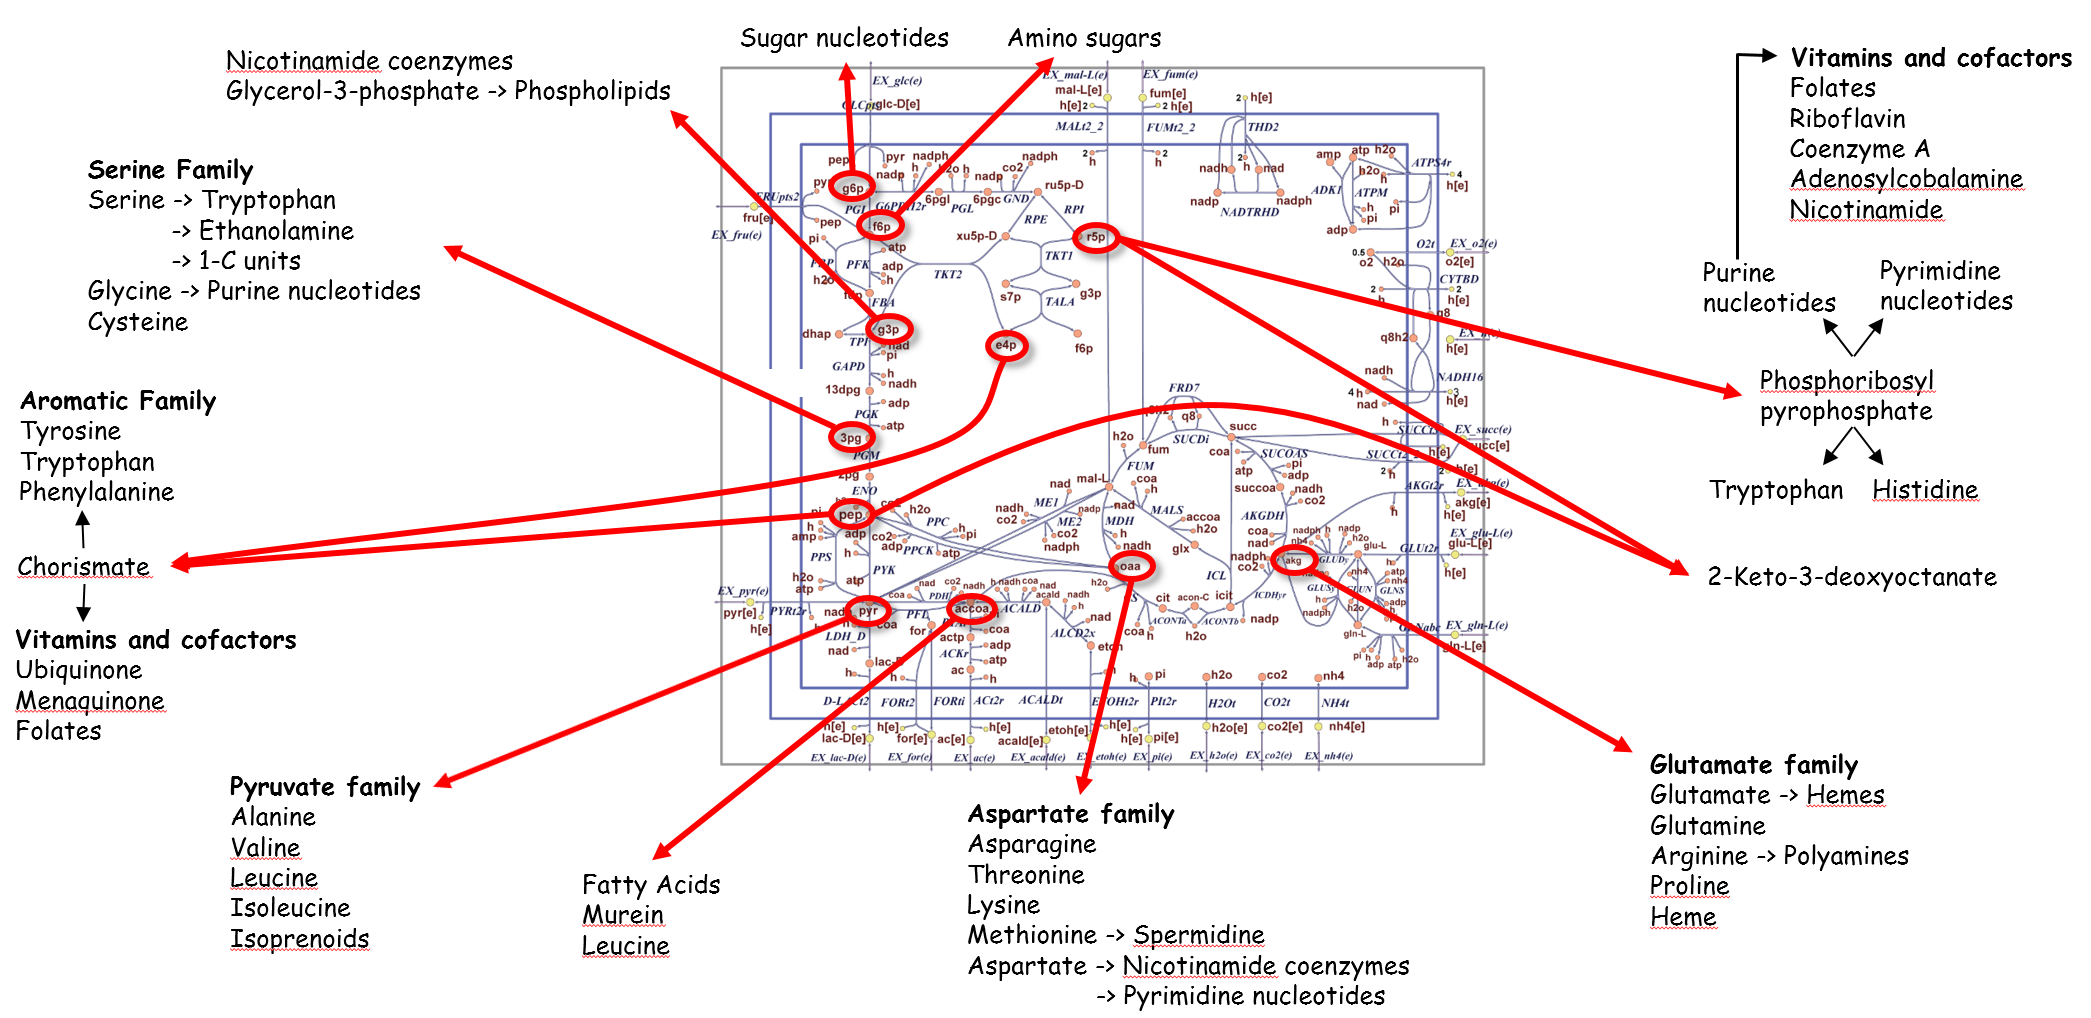

**                                                                                                                Figura 6.** Precursores del modelo central de *E.coli* [11].

La reacción de la biomasa también incluye cofactores clave (`atp[c]`, `adp[c]`, `nad[c]`, `nadh[c]`, `nadph[c]` y `pi[c]`) que son necesarios para el crecimiento y funcionamiento celular. La reacción de la biomasa se basa en mediciones experimentales de los componentes de la biomasa, lo que permite escalar la reacción para que su flujo sea igual a la tasa de crecimiento exponencial (μ) del organismo. Con la biomasa ahora representada en el modelo, la tasa máxima de crecimiento se puede predecir calculando las condiciones que maximizan el flujo a través de la reacción de la biomasa.

La reacción de biomasa y los metabolitos precursores ponderados se pueden inspeccionar imprimiendo la fórmula para la función de biomasa utilizando la función COBRA Toolbox "`printRxnFormula`". *[Tiempo: segundos]*

printRxnFormula(model,'Biomass_Ecoli_core_w_GAM')

Biomass_Ecoli_core_w_GAM	1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] + 0.205 g6p[c] + 0.2557 gln-L[c] + 4.9414 glu-L[c] + 59.81 h2o[c] + 3.547 nad[c] + 13.0279 nadph[c] + 1.7867 oaa[c] + 0.5191 pep[c] + 2.8328 pyr[c] + 0.8977 r5p[c] 	->	59.81 adp[c] + 4.1182 akg[c] + 3.7478 coa[c] + 59.81 h[c] + 3.547 nadh[c] + 13.0279 nadp[c] + 59.81 pi[c] 


ans = 1×1 cell array
    {'1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] + 0.205 g6p[c] + 0.2557 gln-L[c] + 4.9414 glu-L[c] + 59.81 h2o[c] + 3.547 nad[c] + 13.0279 nadph[c] + 1.7867 oaa[c] + 0.5191 pep[c] + 2.8328 pyr[c] + 0.8977 r5p[c]  -> 59.81 adp[c] + 4.1182 akg[c] + 3.7478 coa[c] + 59.81 h[c] + 3.547 nadh[c] + 13.0279 nadp[c] + 59.81 pi[c] '}


La función objetivo también se puede verificar usando la función "`checkObjective(model)`" que imprimirá los coeficientes estequiométricos para cada metabolito junto con el nombre del objetivo. *[Tiempo: segundos]*

checkObjective(model)

summaryT = 23×5 table
    Coefficient    Metabolite    metID            Reaction            RxnID
    ___________    __________    _____    ________________________    _____

       -1.496       3pg[c]         3      Biomass_Ecoli_core_w_GAM     13  
      -3.7478       accoa[c]      10      Biomass_Ecoli_core_w_GAM     13  
        59.81       adp[c]        13      Biomass_Ecoli_core_w_GAM     13  
       4.1182       akg[c]        14      Biomass_Ecoli_core_w_GAM     13  
       -59.81       atp[c]        17      Biomass_Ecoli_core_w_GAM     13  
       3.7478       coa[c]        21      Biomass_Ecoli_core_w_GAM     13  
       -0.361       e4p[c]        23      Biomass_Ecoli_core_w_GAM     13  
      -0.0709       f6p[c]        26      Biomass_Ecoli_core_w_GAM     13  
       -0.129       g3p[c]        33      Bioma

ans = 1×1 cell array
    {'Biomass_Ecoli_core_w_GAM'}


La función objetivo para el modelo central de *E.coli* se configura automáticamente para que sea la reacción de la biomasa. También se puede configurar la función de biomasa para que sea la función objetivo usando model = changeObjective(model,'reaction name'') como se muestra a continuación. *[Tiempo: segundos]*

model = changeObjective(model,'Biomass_Ecoli_core_w_GAM');

### Peguntas

 1.- Que genes están asociados con la reacción '`succinate dehydrogenase (irreversible)'`?

% encontrar id
model.rxnNames(1:90) 

ans = 90×1 cell array
    {'acetaldehyde dehydrogenase (acetylating)'           }
    {'acetaldehyde reversible transport'                  }
    {'acetate kinase'                                     }
    {'aconitase (half-reaction A, Citrate hydro-lyase)'   }
    {'aconitase (half-reaction B, Isocitrate hydro-lyase)'}
    {'acetate reversible transport via proton symport'    }
    {'adenylate kinase'                                   }
    {'2-Oxoglutarate dehydrogenase'                       }
    {'2-oxoglutarate reversible transport via symport'    }
    {'alcohol dehydrogenase (ethanol)'                    }
    {'ATP maintenance requirement'                        }
    {'ATP synthase (four protons for one ATP)'            }
    {'Biomass Objective Function with GAM'                }
    {'CO2 transporter via diffusion'                      }
    {'citrate synthase'                                   }
    {'cytochrome oxidase bd (ubiquinol-8: 2 protons)'     }
    {'D-lactate tr

% numero 89 de la lista
model.rxns(89) % ID = {'SUCDi'}

ans = 1×1 cell array
    {'SUCDi'}



Succinate_d = findGenesFromRxns(model,'SUCDi')

Succinate_d = 1×1 cell array
    {4×1 cell}


disp(Succinate_d{1}) %Genes asociados a la reacción

    {'b0721'}
    {'b0722'}
    {'b0723'}
    {'b0724'}



2.- Que metabolitos pertenecen a esa reacción?

Succinate_mets = findMetsFromRxns(model, 89)

Succinate_mets = 4×1 cell array
    {'fum[c]' }
    {'q8[c]'  }
    {'q8h2[c]'}
    {'succ[c]'}


%metabolitos asociados a la reacción
for i=1:4
    disp(Succinate_mets(i))
end

    {'fum[c]'}

    {'q8[c]'}

    {'q8h2[c]'}

    {'succ[c]'}



3.- Cual es el gen que se asocia con más reacciones?

%lista de genes
gene_ids = model.genes

gene_ids = 137×1 cell array
    {'b0008'}
    {'b0114'}
    {'b0115'}
    {'b0116'}
    {'b0118'}
    {'b0351'}
    {'b0356'}
    {'b0451'}
    {'b0474'}
    {'b0485'}
    {'b0720'}
    {'b0721'}
    {'b0722'}
    {'b0723'}
    {'b0724'}
    {'b0726'}
    {'b0727'}
    {'b0728'}
    {'b0729'}
    {'b0733'}
    {'b0734'}
    {'b0755'}
    {'b0767'}
    {'b0809'}
    {'b0810'}
    {'b0811'}
    {'b0875'}
    {'b0902'}
    {'b0903'}
    {'b0904'}


%lista de reacciones
rxn_ids = model.rxns

rxn_ids = 95×1 cell array
    {'ACALD'                   }
    {'ACALDt'                  }
    {'ACKr'                    }
    {'ACONTa'                  }
    {'ACONTb'                  }
    {'ACt2r'                   }
    {'ADK1'                    }
    {'AKGDH'                   }
    {'AKGt2r'                  }
    {'ALCD2x'                  }
    {'ATPM'                    }
    {'ATPS4r'                  }
    {'Biomass_Ecoli_core_w_GAM'}
    {'CO2t'                    }
    {'CS'                      }
    {'CYTBD'                   }
    {'D_LACt2'                 }
    {'ENO'                     }
    {'ETOHt2r'                 }
    {'EX_ac(e)'                }
    {'EX_acald(e)'             }
    {'EX_akg(e)'               }
    {'EX_co2(e)'               }
    {'EX_etoh(e)'              }
    {'EX_for(e)'               }
    {'EX_fru(e)'               }
    {'EX_fum(e)'               }
    {'EX_glc(e)'               }
    {'EX_gln_L(e)'             }
    {'EX_glu_L(e)

%lista de los genes asociados a reacciones
x = model.rxnGeneMat;

% Inicializar un vector para contar el número de reacciones por gen
gene_reaction_count = zeros(length(gene_ids), 1);

% Contar las reacciones para cada gen
for i = 1:length(rxn_ids)
    % Obtener los genes asociados a la reacción i
    associated_genes = model.rxnGeneMat(i, :);
    % Incrementar el contador para cada gen asociado
    gene_reaction_count(associated_genes > 0) = gene_reaction_count(associated_genes > 0) + 1;
end

% Encontrar el índice del gen con más reacciones
[max_count, max_index] = max(gene_reaction_count);

% Obtener el ID del gen
most_associated_gene = gene_ids{max_index};

% Mostrar el resultado
fprintf('El gen con más reacciones es %s, asociado a %d reacciones.\n', most_associated_gene, max_count);

El gen con más reacciones es s0001, asociado a 5 reacciones.


4.- Cual es la reacción con más metabolitos?

% Obtener la matriz de estequiometría
S = model.S 

S =    (8,1)      -1.0000
  (10,1)       1.0000
  (21,1)      -1.0000
  (43,1)       1.0000
  (50,1)      -1.0000
  (51,1)       1.0000
   (8,2)       1.0000
   (9,2)      -1.0000
   (6,3)      -1.0000
  (12,3)       1.0000
  (13,3)       1.0000
  (17,3)      -1.0000
  (11,4)       1.0000
  (18,4)      -1.0000
  (41,4)       1.0000
  (11,5)      -1.0000
  (41,5)      -1.0000
  (45,5)       1.0000
   (6,6)       1.0000
   (7,6)      -1.0000
  (43,6)       1.0000
  (44,6)      -1.0000
  (13,7)       2.0000
  (16,7)      -1.0000
  (17,7)      -1.0000
  (14,8)      -1.0000
  (19,8)       1.0000
  (21,8)      -1.0000
  (50,8)      -1.0000
  (51,8)       1.0000
  (71,8)       1.0000
  (14,9)       1.0000
  (15,9)      -1.0000
  (43,9)       1.0000
  (44,9)      -1.0000
   (8,10)      1.0000
  (24,10)     -1.0000
  (43,10)      1.0000
  (50,10)     -1.0000
  (51,10)      1.0000
  (13,11)      1.0000
  (17,11)     -1.0000
  (41,11)     -1.0000
  (43,11)      1.0000
  (60,11)      1.0000
  (13,


% Contar el número de metabolitos por reacción
num_metabolites_per_rxn = sum(S ~= 0, 1); % Sumar las columnas donde hay metabolitos

% Paso 3: Encontrar la reacción con más metabolitos
[max_metabolites, max_index] = max(num_metabolites_per_rxn); % Encuentra el máximo
max_metabolites = full(max_metabolites);
reaction_with_most_metabolites = model.rxns{max_index}; % Obtener el ID de la reacción

% Mostrar el resultado
fprintf('La reacción con más metabolitos es %s, asociada a %d metabolitos.\n', reaction_with_most_metabolites, max_metabolites)

La reacción con más metabolitos es Biomass_Ecoli_core_w_GAM, asociada a 23 metabolitos.


5.- Cuales son los precursores de esos metabolitos?

reaction_index = max_index; % Índice de la reacción con más metabolitos
associated_metabolites = find(S(:, reaction_index) ~= 0); % Encuentra los metabolitos asociados

% Inicializa una lista para los precursores
precursors = {};

% Itera sobre cada metabolito asociado
for i = 1:length(associated_metabolites)
    metabolite_index = associated_metabolites(i);
    % Encuentra las reacciones donde este metabolito es un producto
    reactions_for_metabolite = find(S(metabolite_index, :) > 0);
    
    % Agrega los metabolitos que son reactivos en estas reacciones
    for j = 1:length(reactions_for_metabolite)
        precursor_reaction_index = reactions_for_metabolite(j);
        % Encuentra los metabolitos en la reacción que son reactivos (precursores)
        precursor_indices = find(S(:, precursor_reaction_index) < 0); % Solo precursores (negativos)
        
        % Añade los precursores a la lista
        for k = 1:length(precursor_indices)
            precursor = model.mets{precursor_indices(k)};
            if ~ismember(precursor, precursors) % Evita duplicados
                precursors{end+1} = precursor; % Agrega el precursor
            end
        end
    end
end

% Mostrar los precursores encontrados
disp('Precursores de los metabolitos asociados:')

Precursores de los metabolitos asociados:


disp(precursors)

    {'2pg[c]'}    {'acald[c]'}    {'coa[c]'}    {'nad[c]'}    {'pyr[c]'}    {'ac[c]'}    {'atp[c]'}    {'amp[c]'}    {'h2o[c]'}    {'3pg[c]'}    {'accoa[c]'}    {'e4p[c]'}    {'f6p[c]'}    {'g3p[c]'}    {'g6p[c]'}    {'gln-L[c]'}    {'glu-L[c]'}    {'nadph[c]'}    {'oaa[c]'}    {'pep[c]'}    {'r5p[c]'}    {'nh4[c]'}    {'gln-L[e]'}    {'succ[c]'}    {'akg[e]'}    {'h[e]'}    {'nadp[c]'}    {'icit[c]'}    {'adp[c]'}    {'pi[c]'}    {'h[c]'}    {'glx[c]'}    {'s7p[c]'}    {'fdp[c]'}    {'fru[e]'}    {'xu5p-D[c]'}    {'dhap[c]'}    {'glc-D[e]'}    {'akg[c]'}    {'glu-L[e]'}    {'cit[c]'}    {'o2[c]'}    {'q8h2[c]'}    {'h2o[e]'}    {'ac[e]'}    {'etoh[c]'}    {'lac-D[e]'}    {'etoh[e]'}    {'for[e]'}    {'fum[e]'}    {'lac-D[c]'}    {'mal-L[e]'}    {'mal-L[c]'}    {'6pgl[c]'}    {'pi[e]'}    {'co2[c]'}    {'pyr[e]'}    {'succ[e]'}    {'nadh[c]'}    {'q8[c]'}    {'6pgc[c]'}



6.- Cuales son los 4 metabolitos que participan en más reacciones?

% imprimir total de metabolitos, lista de 72
model.mets

ans = 72×1 cell array
    {'13dpg[c]' }
    {'2pg[c]'   }
    {'3pg[c]'   }
    {'6pgc[c]'  }
    {'6pgl[c]'  }
    {'ac[c]'    }
    {'ac[e]'    }
    {'acald[c]' }
    {'acald[e]' }
    {'accoa[c]' }
    {'acon-C[c]'}
    {'actp[c]'  }
    {'adp[c]'   }
    {'akg[c]'   }
    {'akg[e]'   }
    {'amp[c]'   }
    {'atp[c]'   }
    {'cit[c]'   }
    {'co2[c]'   }
    {'co2[e]'   }
    {'coa[c]'   }
    {'dhap[c]'  }
    {'e4p[c]'   }
    {'etoh[c]'  }
    {'etoh[e]'  }
    {'f6p[c]'   }
    {'fdp[c]'   }
    {'for[c]'   }
    {'for[e]'   }
    {'fru[e]'   }


mets = zeros(length(model.mets), 1);
% Contar las reacciones en que participa cada metabolito
for i=1:length(mets)
    met_counts = find(S(i,:) ~= 0);
    mets(i) = length(met_counts);
end

% Usar sort para obtener los valores ordenados y sus índices
[sorted_values, sorted_indices] = sort(mets, 'descend');

% Obtener los 4 valores máximos (puedes ajustar este número)
num_max_values = 4;
top_values = sorted_values(1:num_max_values);
top_indices = sorted_indices(1:num_max_values);

% Mostrar resultados
fprintf('Los %d valores máximos son:\n', num_max_values);

Los 4 valores máximos son:


disp(top_values);

    35
    18
    17
    13



fprintf('Sus índices son:\n');

Sus índices son:


disp(top_indices);

    43
    41
    44
    17




%imprimir nombres de metabolitos
for i = 1:4
    index = top_indices(i);
    fprintf('Metabolito más utilizado en más reacciones: %s\n', model.mets{index});
end

Metabolito más utilizado en más reacciones: h[c]
Metabolito más utilizado en más reacciones: h2o[c]
Metabolito más utilizado en más reacciones: h[e]
Metabolito más utilizado en más reacciones: atp[c]


7.- Cuales crees que son confactores mas importantes en el modelo *E.coli*?

model.mets

ans = 72×1 cell array
    {'13dpg[c]' }
    {'2pg[c]'   }
    {'3pg[c]'   }
    {'6pgc[c]'  }
    {'6pgl[c]'  }
    {'ac[c]'    }
    {'ac[e]'    }
    {'acald[c]' }
    {'acald[e]' }
    {'accoa[c]' }
    {'acon-C[c]'}
    {'actp[c]'  }
    {'adp[c]'   }
    {'akg[c]'   }
    {'akg[e]'   }
    {'amp[c]'   }
    {'atp[c]'   }
    {'cit[c]'   }
    {'co2[c]'   }
    {'co2[e]'   }
    {'coa[c]'   }
    {'dhap[c]'  }
    {'e4p[c]'   }
    {'etoh[c]'  }
    {'etoh[e]'  }
    {'f6p[c]'   }
    {'fdp[c]'   }
    {'for[c]'   }
    {'for[e]'   }
    {'fru[e]'   }


1. NAD+ (Nicotinamida adenina dinucleótido) es un cofactor que actúa como un transportador de electrones en reacciones de oxidación-reducción. Fndamental en el metabolismo energético, participando en reacciones como la glucólisis y el ciclo del ácido cítrico (Krebs). Su forma reducida, NADH, es crucial para la producción de ATP en la cadena de transporte de electrones.

2. NADP+ (Nicotinamida adenina dinucleótido fosfato)

Descripción: Similar a NAD+, pero con un grupo fosfato adicional. NADP+ se convierte en NADPH al aceptar electrones. Es importante en reacciones biosintéticas, como la síntesis de ácidos grasos y la biosíntesis de nucleótidos, y actúa como un agente reductor en varias rutas anabólicas.

3. FAD (Flavin adenina dinucleótido)

Descripción: FAD es otro cofactor de transporte de electrones que puede aceptar dos electrones y dos protones para formar FADH2. Participa en reacciones de oxidación-reducción, en el ciclo del ácido cítrico y en la cadena de transporte de electrones, contribuyendo a la producción de ATP.

4. CoA (Coenzima A)

Descripción: CoA es un cofactor esencial que transporta grupos acilo, como grupos acetilo. Crucial para el metabolismo de ácidos grasos y el ciclo del ácido cítrico, participando en la formación de acetil-CoA, que es un metabolito clave en la producción de energía.

5. Mg²+ (Magnesio)

Descripción: Ion metálico que actúa como cofactor en muchas enzimas. Esencial para la actividad de varias enzimas que requieren ATP, ayudando en la estabilización de ATP y en reacciones de fosforilación.

6. Fe²+ (Hierro)

Descripción: Ion metálico que forma parte de varios complejos enzimáticos. Es un cofactor en muchas enzimas, incluyendo aquellas que participan en la síntesis de nucleótidos y en el metabolismo del oxígeno.

7. Zn²+ (Zinc)

Descripción: Ion metálico que actúa como cofactor en diversas enzimas. Es importante para la función de muchas enzimas involucradas en la síntesis de proteínas y en la regulación de la expresión génica.

8.- Cual es la unidad de flujo de una reacción? (Pista: 2.E. Restricciones del modelo)


$$\mathrm{mmol}\cdot {\mathrm{gDW}}^{-1} \cdot {\mathrm{hr}}^{-1}$$


cantidad de milimoles de un metabolito producido o consumido por gramo de peso seco celular en una hora